# Ballbot robust stability analysis and validation script

**Contents:**

- Nonlinear model synthesis with distrubances

- Parametric linearisation 

- Parametric uncertainty introduction

- optimisation based worst case search

- Disturbance rejection and noise attenutation

- H-infinity controller synthesis

- based on linear systems 

- based on worst case system

- Comparison of behavior with nonlinear model

clear all

## Model physical parameters definition

Introducing the physical parameters of the system

global rK_n rW_n  rA_n  l_n  mAW_n mK_n  A_ThetaAWx_n  A_ThetaAWy_n  A_ThetaAWz_n  ThetaKi_n  ThetaWi_n;

% Uncertain parameters
rK_n = 0.120; % radius of the ball
rW_n = 0.05; % radius of omni wheel=5cm
rA_n = 0.126; % radius of the body  
l_n = 0.22634; % distance between centre of ball and centre of gravity of the body 
mAW_n = 6.71; % mass of the body and omni wheel  
mK_n = 0.625; % mass of the basket ball  
A_ThetaAWx_n = 1.41271413; % Inertia of the body and Omni wheels in the body reference frame A  
A_ThetaAWy_n = 1.41271311;
A_ThetaAWz_n = 0.05359646;
ThetaKi_n = 0.003606375;
ThetaWi_n = 0.01504; 

% Angle of motors
alpha = 47*pi/180;
beta1 = 0;
beta2 = 2/3*pi;
beta3 = 4/3*pi;

% vector of nominal parameters
params_n = [rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n];

## Derivation script of the nonlinear model

Modeling ot the nonlinear system - extended matlab version of the script FInal.nb made in Mathematica

- Parametric nonlinear model creation

- Linearization around 0

- Creation of simulation functions for further analyisis - linear and nonlinear

Execution can take 5-10 minutes

model_script_disturbance;

Model physical parameters
Coordinate system transformations
Binding equations
Energies
Non-potential forces
Lagrange
Elapsed time is 4.292360 seconds.
Linear equation solving
Elapsed time is 8.124125 seconds.
State space representation
Elapsed time is 51.688543 seconds.
Creating a matlab function from nonlinear model
This may take few minutes
Elapsed time is 61.023455 seconds.
Adding linearisation point
Linearisation x0
A matrix
10/10
Elapsed time is 32.405915 seconds.
B matrix
Elapsed time is 4.010573 seconds.
W matrix
Elapsed time is 1.572868 seconds.
Create A and B and W parametric functions - physical parameters
Elapsed time is 24.591562 seconds.
Model script done


## Linear nominal model sysnthesys

Creation of linear transfer funciton based on linearised matrices of the Ballbot and the nominal parameters

Additionally the LQR controller is provided (based on the LQR controller in the report) as a default controller to be compared in further analysis.


% A matrix
tic
A_n= fA(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('A matrix :  %f sec\n',toc);

A matrix :  0.407333 sec


% B matrix
tic
B_n= fB(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B matrix :  %f sec\n',toc);

B matrix :  1.314777 sec


% B_w matrix
tic
B_w= fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B_w matrix :  %f sec\n',toc);

B_w matrix :  0.368286 sec



% state space model from matrices
G_n = ss(A_n, B_n, eye(10), zeros(10,3));


LQR controller synthesis


% LQR controller design
Q = diag([100 50 100 50 40 20 20 10 20 10]);
R = diag([100 100 100]);
K_lqr = lqr(G_n,Q,R);

## Linear and nonlinear model initial condition response comparison

Finally, simple graph of initial condition response for linear and nonlinear system with nominal parameters to see how well does the lienarized system corespond with the nonlinear

nonlinear system simulation
Nonlinear simulation: 4.00 sec / 4.00 sec
Elapsed time is 30.404261 seconds.
lienar system simulation
Elapsed time is 0.266219 seconds.


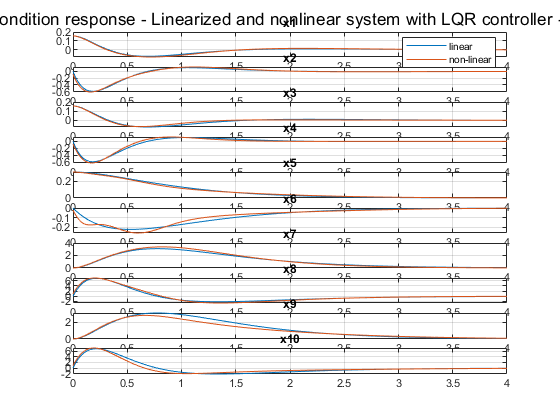

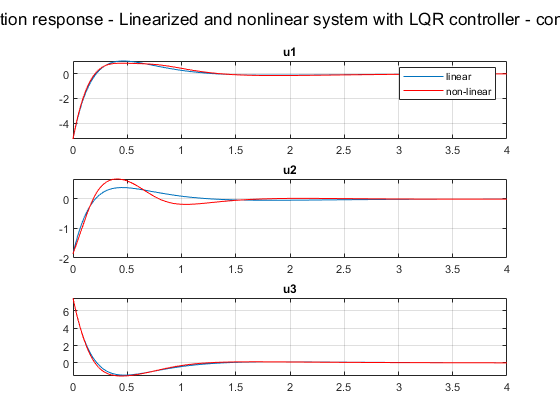

X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_max = 4; %s
initialplot_compare_nlin(@nlin_model_n,G_n,K_lqr,X0,T_max,1,2)

drawnow

## Introducing the uncertainties

The uncertainties are introduced into the physiscal parameters of the system. The idea is that for the variables you cannot measure you should have some uncertainty about their values. 

The uncertainties are set as the percentage.For example if l_var is 20, that means that your height of center of mass can be +-20% different than your nominal value.

Sample uncertain models
Uncertain model visualisation - initial condition response
It may take few minutes


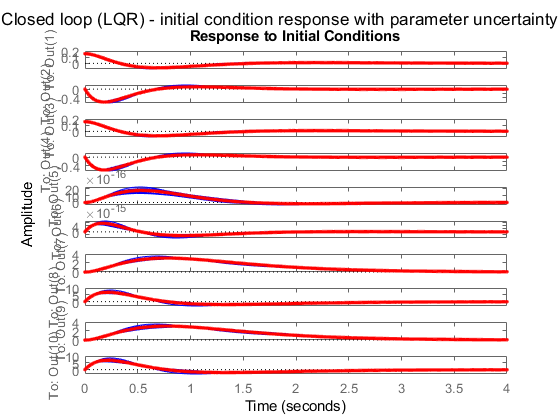

Elapsed time is 47.681565 seconds.
Uncertain model visualisation - singular value plot
It may take few minutes


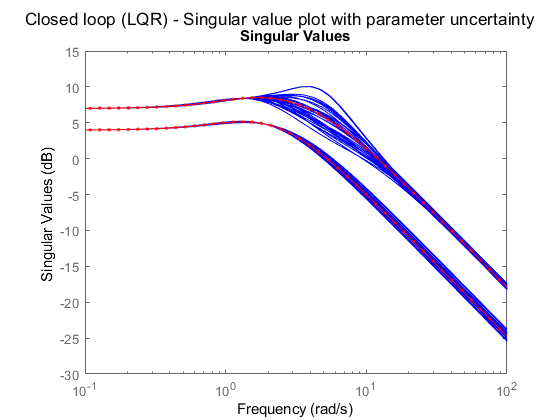

Elapsed time is 13.651350 seconds.


% Uncertain variation of the parameters
A_ThetaAWx_var = 15; % percent
l_var = 10; % percent
A_ThetaAWz_var = 15;% percent
ThetaKi_var = 15;% percent
A_ThetaAWy_var = 15; % percent
ThetaWi_var = 15;% percent

% sample the uncertain models
visualize_uncertainty_samples

## Find the worst case system based on parameter uncertainties

To be able to find the worst case parameters we define the optimisation problem based on disk margin. 

Basically we are changing the parameter values and searching to the minimum of the stability margin (diskmargin)

The minimal margin corresponds to the worst case parameters

wcu = find_wcu_optimisation(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr)

Constrained optimisation approach to finding worst case condition
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    1.579285e-01    0.000e+00    8.690e-02
    1      14    1.525165e-01    0.000e+00    4.953e-02    2.067e-02
    2      21    9.281244e-02    0.000e+00    1.011e-01    1.940e-01
    3      28    8.582947e-02    0.000e+00    5.311e-02    2.796e-02
    4      35    8.654095e-02    0.000e+00    4.710e-02    7.337e-03
    5      43    8.635973e-02    0.000e+00    1.797e-02    5.018e-03
    6      50    8.622868e-02    0.000e+00    1.246e-02    3.523e-03
    7      57    8.622411e-02    0.000e+00    9.819e-03    1.092e-03
    8      64    8.622708e-02    0.000e+00    1.046e-01    1.282e-03
    9      76    8.622530e-02    0.000e+00    1.634e-02    2.272e-03
   10      87    8.622177e-02    0.000e+00    1.725e-03    2.258e-03
   11      94    8.369458e-02    0.000e+00    1.28

X =     0.9007    1.1488    0.9304    1.1490    1.0072    1.0024


FVAL = 0.0837

EXITFLAG = 2

Construct the worst case sample


wcu = struct with fields:
             l: 0.2039
       ThetaWi: 0.0173
       ThetaKi: 0.0034
    A_ThetaAWx: 1.6232
    A_ThetaAWy: 1.4229
    A_ThetaAWz: 0.0537
    min_margin: 0.0837
             G: [10×3 ss]
      max_gain: Inf


% variable wcu contains 
% wcu.l,ThetaKi,... - the worst case parameters 
% wcu.min_margin    - worst case margin
% wcu.max_gain      - worst case gain
% wcu.G             - linear state space model of the worst case transfer function

## Nominal and worst case linear model comparison

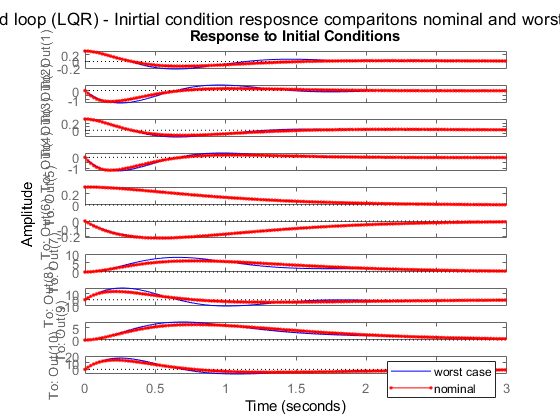

% initialplot
X0 = [pi/10 0 pi/10 0 pi/10 0 0 0 0 0]';
T_sim = 3; %sec
figure(110);
initialplot(feedback(wcu.G,K_lqr),'b',X0,T_sim); 
hold on;
initialplot(feedback(G_n,K_lqr),['' ...
    'r'],X0,T_sim);
legend('worst case','nominal')
sgtitle('Closed loop (LQR) - Inirtial condition resposnce comparitons nominal and worst case')

drawnow

## Singular value plota

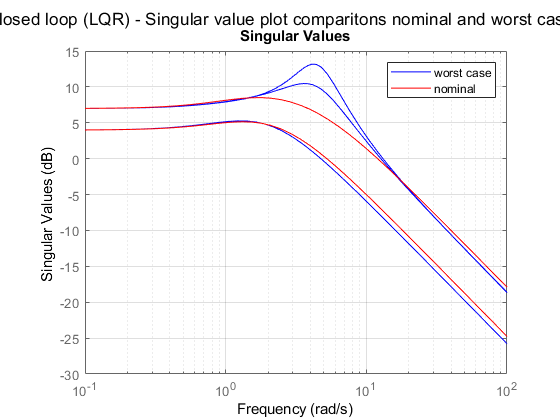

figure(111);
sigma(feedback(wcu.G,K_lqr),'b');
hold on;
sigma(feedback(G_n,K_lqr),'r');
legend('worst case','nominal')
grid on;
sgtitle('Closed loop (LQR) - Singular value plot comparitons nominal and worst case')

drawnow

## Validate worst case performance with the nonlinear model

Interesting is to see if nonlinear system is still stable for worst case parameters and LQR controller calculated for the nominal parameters.

Creating a matlab function from nonlinear model
This may take few minutes
Writing function in the file
Elapsed time is 63.309134 seconds.
Simulate and compare worst case linear and nonliner
nonlinear system simulation
Nonlinear simulation: 4.00 sec / 4.00 sec
Elapsed time is 29.830466 seconds.
lienar system simulation
Elapsed time is 0.072733 seconds.


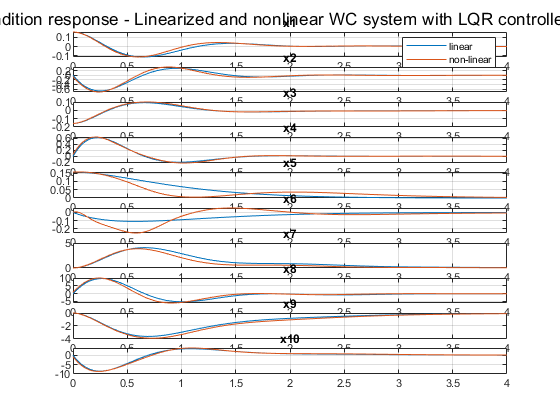

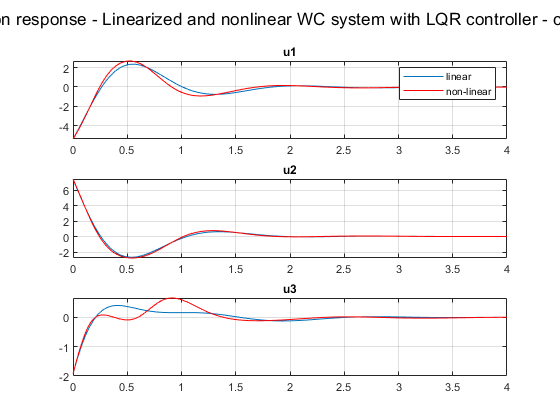

visualize_nonlinear_worst_case;

drawnow

# Distrubance rejection and noise attenuation

#### **Ballbot has two type of disturbance **

 - ***force acting on the body - hunam interaction ****(w)*

 - ***measurement noise *** (*n*)

   > acceletometer and gyro

   > influences thetax, d_thetax, thetay, d_thetay  

#### ** Ballbot system**

 dx = Ax + [B_n B_w B_u]*[w n u]'

 y = Cx + [D_n D_w D_u]*[w n u]'

 u = K*x

% definining the standardized testing input for distrubance rejection
t_d = linspace(0,10,1000);
N_d = length(t_d);
n = randn(4,N_d);
n = n/max(n(:));
wx = [zeros(1,0.2*N_d), ones(1,0.1*N_d), zeros(1,0.7*N_d)];
wy = [zeros(1,0.7*N_d), -ones(1,0.1*N_d) zeros(1,0.2*N_d)];
dist = [n; wx; wy];

figure(200);
for i = 1:4
    subplot(6,1,i);
    plot(t_d,dist(i,:),'LineWidth',1.5);
    hold on
    title(strcat('n',num2str(i)))
end
for i = 1:2
    subplot(6,1,4+i);
    plot(t_d,dist(4+i,:),'LineWidth',1.5);
    hold on
    title(strcat('w',num2str(i)))
end
sgtitle('Testing input signal - measurement noiser and disturbance force on the body')

## Creating the factorial representaion

% disturbance matrix
B_w = fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
% noise matrix
B_n = zeros(10,4);
% measurement noise variance 1 degree 
D_n = 0.5/180*pi*eye(10,4); 
% input D matrix
D_u = zeros(10,5);
C_z = [G_n.c; zeros(3,10)];
D_z = [D_n  D_u ; [zeros(3,6) 30*eye(3)]];
% model for h-infinity synthesis containing z output
Pz = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_z; [D_n D_u] ]);
D_y = [D_n  D_u ; [zeros(3,6) eye(3)]];
% model for simulation using y as output
P = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_y; [D_n D_u] ]);

## Initial LQR disturbance rejection

Compariosn of linear and nonliner performcane using nominal and worst case parameters

% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_n,K_lqr,dist,t_d,P,201);

nonlinear system simulation
Nonlinear simulation: 10.00 sec / 

sgtitle('Closed loop LQR linear vs nonlinear model with nominal parameters parameters')

% worst case model
% disturbance matrix
B_w_wcu = fW(rK_n, rW_n, rA_n, wcu.l, mAW_n, mK_n, wcu.A_ThetaAWx, wcu.A_ThetaAWy, wcu.A_ThetaAWz, wcu.ThetaKi, wcu.ThetaWi);
% model for h-infinity synthesis containing z output
Pz_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_z; [D_n D_u]]);
% model for simulation using y as output
P_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_y; [D_n D_u]]);

% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_wcu,K_lqr,dist,t_d,P_wc,202);
sgtitle('Closed loop LQR linear vs nonlinear model with worst case parameters')

Singular value plot for disturbance rejection fonominal and worst case model

% plot singular values of distrurbance rejection loop
figure(301)
sigma(lft(P,-K_lqr),'r',lft(P_wc,-K_lqr),'b',(0.1:0.01:100));
legend('nominal','worst case');
grid on
title('Singular values plot for distrubance rejection closed loop with LQR')


## H-infinity controller design

Fixed structure - gain U=K*x;

%% H-infinity controller design fixed
% hinf fixed structure - gain
K_tun = realp('K_t',ones(3,10));   
K_tun.Minimum = -100*ones(3,10); 
K_tun.Maximum = 100*ones(3,10);
[C,gamma,info] = hinfstruct(Pz_wc,-K_tun);
K_hinf = C.Blocks.K_t.Value

## **Comparation of H-infinity and LQR **

%plot singular values of distrurbance rejection loop
figure(302)
sigma(lft(P,-K_hinf),'r',lft(P_wc,-K_hinf),'b',lft(P,-K_lqr),'--r',lft(P_wc,-K_lqr),'--b',(0.1:0.01:100));
legend('nominal H-inf','worst case H-inf','nominal LQR','worst case LQR');
grid on
title('Singular values plot for distrubance rejection closed loop with H-infinity')
%%complarison H-infinity and LQR linear models
figure(303)
lsim(lft(P,-K_hinf),lft(P,-K_lqr),dist,t_d);
sgtitle('H-Infinity and LQR comparison on disturbance rejection nominal linear proces')
figure(304)
lsim(lft(P_wc,-K_hinf),lft(P_wc,-K_lqr),dist,t_d);
sgtitle('H-Infinity and LQR comparison on disturbance rejection worst case linear proces')
%% complarison H-infinity and nonlinear model
nlsim(@nlin_model_wcu,K_hinf,dist,t_d,P_wc,305);
sgtitle('Closed loop H-infinity linear vs nonlinear model with worst case parameters')
nlsim(@nlin_model_n,K_hinf,dist,t_d,P,306);
sgtitle('Closed loop H-infinity linear vs nonlinear model with nominal parameters')


## Full H-infinity controller 

No fixed structure it can be any state space model

%% H-infinity controller design not fixed
%% hinf controller general
nmeas = 10;
ncont = 3;
opts = hinfsynOptions('Display','on');
[K_hinf_f,CL,gamma] = hinfsyn(Pz,nmeas,ncont,opts);

## Comparison LQR and H-inifnity full

figure(404)
lsim(lft(P,K_hinf_f),lft(P,-K_lqr),dist,t_d);
legend('h-inf full','lqr');


## Bode diagram of LQR, H-infinity fixed and H-infinity full

We can see that Full H-infinity controller has lowest gain for almost all the transfrer functions on the plot making it the most robustly stable one.

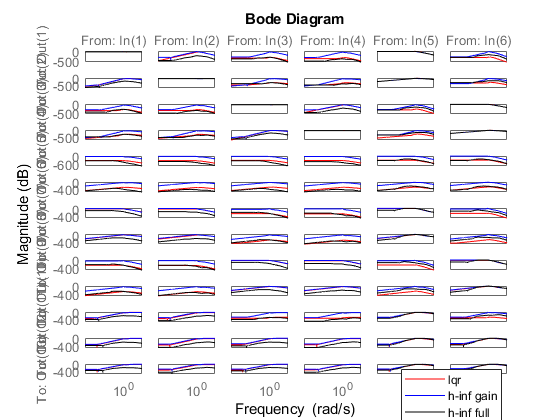

figure(405)
bodemag(lft(P,K_lqr),'r',lft(P,K_hinf),'b',lft(P,K_hinf_f),'k');
legend('lqr','h-inf gain','h-inf full')